# fanuc M6ib

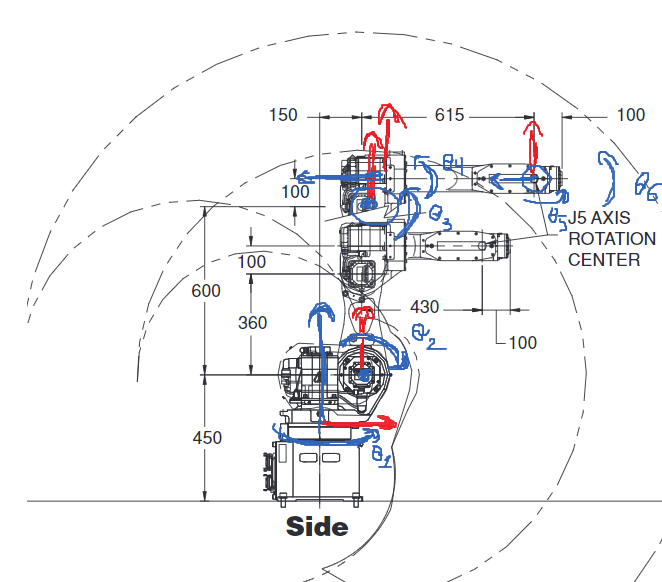

 %these are the lengths of the links and offsets between joints switch out
 %the L2 and D3 if you are using the smaller or bigger robot
L1 = 150;
%big
L2 = 600;
D3 = 615;
%small
%L2 = 360;
%D3 = 430;
L3 = 100;


L(1) = Link('alpha', 0,'a', 0,'d', 0,'modified');
L(2) = Link('alpha', -90*pi/180,'a', L1,'d', 0, 'offset', -90/180*pi,'modified');
L(3) = Link('alpha', 180*pi/180,'a', L2,'d', 0,'modified');
L(4) = Link('alpha', -90*pi/180,'a', L3,'d', -D3,'modified');
L(5) = Link('alpha', 90*pi/180,'a', 0,'d', 0,'modified');
L(6) = Link('alpha', -90*pi/180,'a', 0,'d', 0,'modified');

Fanucm6ib=SerialLink(L, 'name','M6ib');

%Fanucm6ib.teach();

## position

%start by finding the transformation matrixes between each point
syms THETA1 THETA2 THETA3 THETA4 THETA5 THETA6
PI = sym(pi);

ET01=TDH( 0*PI/180,0,0,THETA1);
ET12=TDH(-90*PI/180,L1,0,THETA2-90*PI/180);
ET23=TDH(180*PI/180,L2,0,THETA3+THETA2);
ET34=TDH(-90*PI/180,L3,-D3,THETA4);
ET45=TDH(90*PI/180,0,0,THETA5);
ET56=TDH(-90*PI/180,0,0,THETA6);
ET06=ET01*ET12*ET23*ET34*ET45*ET56;
ET6W=[1  0  0    0;
      0 -1  0    0;
      0  0 -1 -100;
      0  0  0    1];%the wrist is turned around and placed 100mm further out

simplify(ET01)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{THETA}}_{1}\right) & -\sin\left({\mathrm{THETA}}_{1}\right) & 0 & 0\\ \sin\left({\mathrm{THETA}}_{1}\right) & \cos\left({\mathrm{THETA}}_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(ET12)

$$ans = \left(\begin{array}{cccc} \sin\left({\mathrm{THETA}}_{2}\right) & \cos\left({\mathrm{THETA}}_{2}\right) & 0 & 150\\ 0 & 0 & 1 & 0\\ \cos\left({\mathrm{THETA}}_{2}\right) & -\sin\left({\mathrm{THETA}}_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(ET23)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{THETA}}_{2}+{\mathrm{THETA}}_{3}\right) & -\sin\left({\mathrm{THETA}}_{2}+{\mathrm{THETA}}_{3}\right) & 0 & 600\\ -\sin\left({\mathrm{THETA}}_{2}+{\mathrm{THETA}}_{3}\right) & -\cos\left({\mathrm{THETA}}_{2}+{\mathrm{THETA}}_{3}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(ET34)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{THETA}}_{4}\right) & -\sin\left({\mathrm{THETA}}_{4}\right) & 0 & 100\\ 0 & 0 & 1 & -615\\ -\sin\left({\mathrm{THETA}}_{4}\right) & -\cos\left({\mathrm{THETA}}_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(ET45)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{THETA}}_{5}\right) & -\sin\left({\mathrm{THETA}}_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left({\mathrm{THETA}}_{5}\right) & \cos\left({\mathrm{THETA}}_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(ET56)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{THETA}}_{6}\right) & -\sin\left({\mathrm{THETA}}_{6}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left({\mathrm{THETA}}_{6}\right) & -\cos\left({\mathrm{THETA}}_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## actual calculations for forward kinematics

%the wanted angles
theta1 = 0*pi/180;
theta2 = 0*pi/180;
theta3 = 0*pi/180;
theta4 = 0*pi/180;
theta5 = 0*pi/180;
theta6 = 0*pi/180;

T01=TDH( 0*pi/180,0,0,theta1);
T12=TDH(-90*pi/180,L1,0,theta2-90*pi/180);
%the theta3 and theta2 are put together beacuse it works like this in the
%controller on the fanuc
T23=TDH(180*pi/180,L2,0,theta3+theta2);
T34=TDH(-90*pi/180,L3,-D3,theta4);
T45=TDH(90*pi/180,0,0,theta5);
T56=TDH(-90*pi/180,0,0,theta6);


The final matrix from 0 to 6

T06 = T01 * T12 * T23 * T34 * T45 * T56

T06 =     0.0000    0.0000   -1.0000  765.0000
   -0.0000    1.0000    0.0000   -0.0000
    1.0000    0.0000    0.0000  700.0000
         0         0         0    1.0000


R06 = tr2rpy(T06,'deg','zyx');

POS=[T06(1,4),T06(2,4),T06(3,4),R06(1), R06(2), R06(3)]

POS =   765.0000   -0.0000  700.0000         0  -90.0000   -0.0000


Add the wrist transformation

T6W=transl(0,0,-100)*trotz(180*pi/180)*troty(180*pi/180)*trotx(0*pi/180)

T6W =      1     0     0     0
     0    -1     0     0
     0     0    -1  -100
     0     0     0     1


TBW=T06*T6W

TBW =     0.0000   -0.0000    1.0000  865.0000
   -0.0000   -1.0000   -0.0000   -0.0000
    1.0000   -0.0000   -0.0000  700.0000
         0         0         0    1.0000



R = tr2rpy(TBW,'deg','zyx');

POS=[TBW(1,4),TBW(2,4),TBW(3,4),R(1), R(2), R(3)]

POS =   865.0000   -0.0000  700.0000         0  -90.0000  180.0000


## inverse kinematics

As a start we are gonna compare the target frame with our forward kinematics

Now we have to find the easiest parts to identify

theta1 being by far the easiest to find is the one we start with, but remember we are a little offset thanks to the wrist

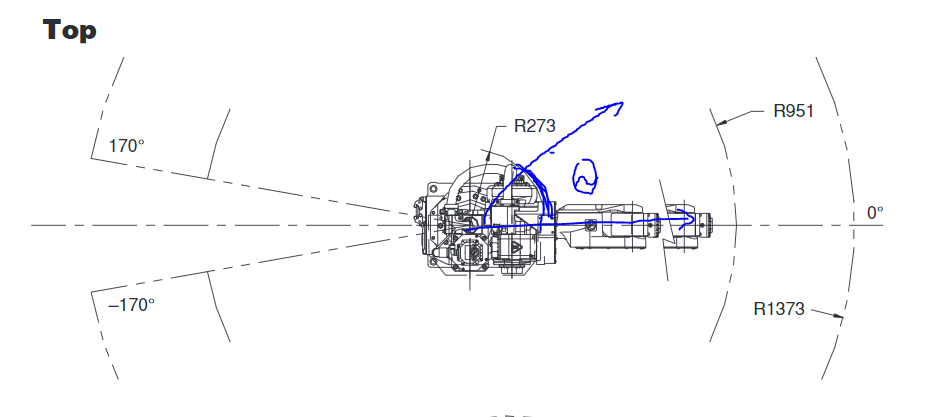

syms X Y Z
theta1=atan2(Y,X);

Next we can look at theta 2 and 3

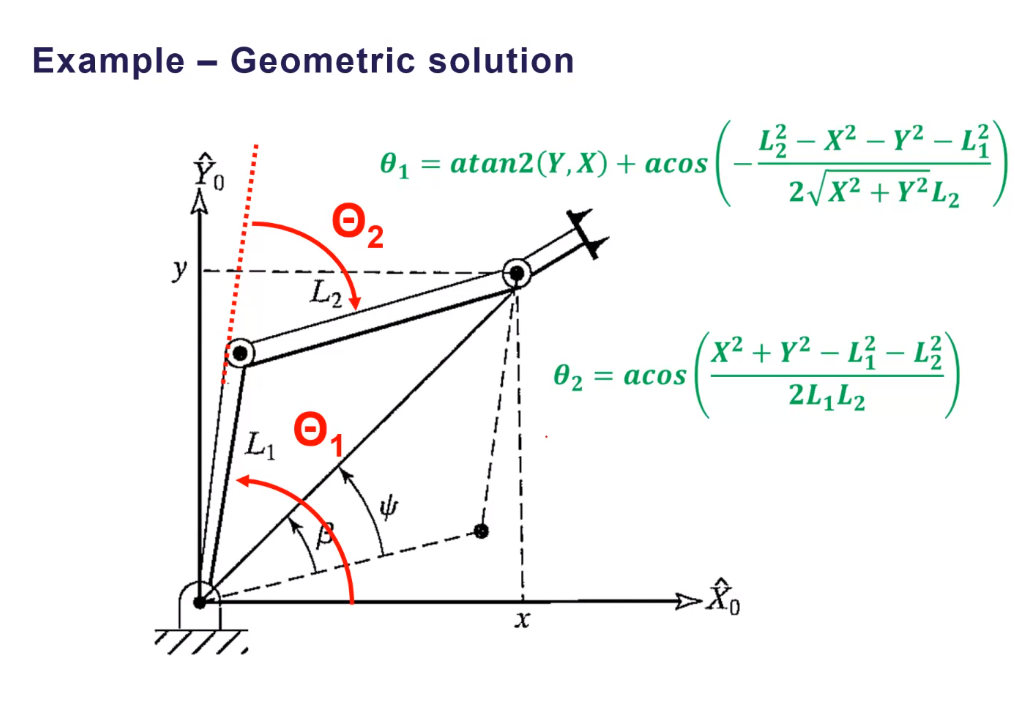

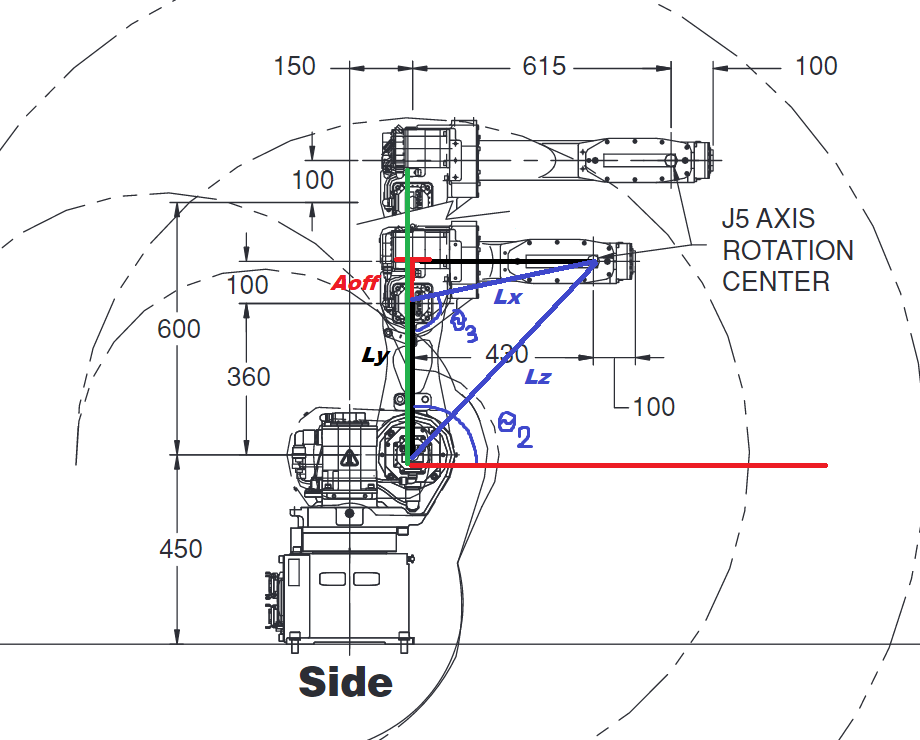

Tho be aware that our theta 2 and 3 move in oppsites from the example, and that the off set does not move with the robot, resulting in movement like this which means theta 3 has a different triangle than theta 2. Also keep in mind that the base is not located in the end of this triangle.

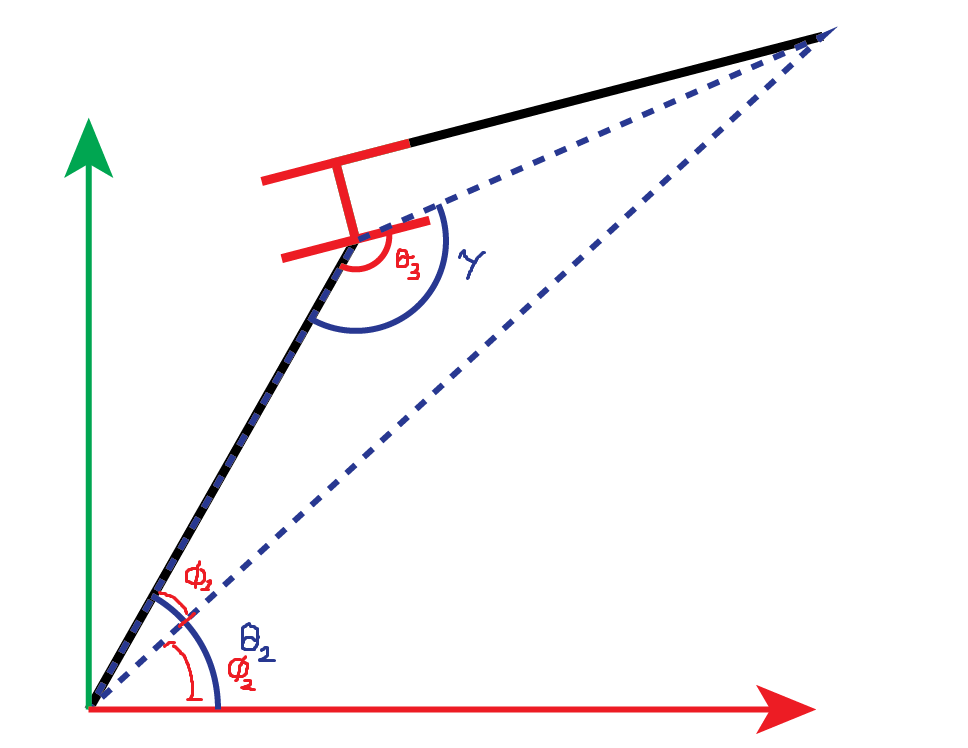

The difference between gamma and theta three can be found my finding the angle of the upper triangles angle and that is then equal to that difference

%Lz=sqrt(T16D(3,4)^2+(T16D(1,4)-L1)^2);
%Lx=sqrt(L3^2+D3^2);
%Ly=L2;
%phi1=acos(-(Lx^2-Lz^2-Ly^2)/(2*Lz*Ly));
%phi2=atan2(T16D(3,4),T16D(1,4)-L1);
%gamma=acos((Lz^2-Ly^2-Lx^2)/(2*Ly*Lx));
%gammadif=atan(L3/D3);

%theta2=pi/2-(phi2+phi1);
%theta3=pi/2-(gamma+gammadif);

Now we can compare this to the transform matrix from 4 to 6 since the first 3 angles are already covered

ET46=ET34*ET45*ET56

$$ET46 = \left(\begin{array}{cccc} \cos\left({\mathrm{THETA}}_{4}\right)\,\cos\left({\mathrm{THETA}}_{5}\right)\,\cos\left({\mathrm{THETA}}_{6}\right)-\sin\left({\mathrm{THETA}}_{4}\right)\,\sin\left({\mathrm{THETA}}_{6}\right) & -\cos\left({\mathrm{THETA}}_{6}\right)\,\sin\left({\mathrm{THETA}}_{4}\right)-\cos\left({\mathrm{THETA}}_{4}\right)\,\cos\left({\mathrm{THETA}}_{5}\right)\,\sin\left({\mathrm{THETA}}_{6}\right) & -\cos\left({\mathrm{THETA}}_{4}\right)\,\sin\left({\mathrm{THETA}}_{5}\right) & 100\\ \cos\left({\mathrm{THETA}}_{6}\right)\,\sin\left({\mathrm{THETA}}_{5}\right) & -\sin\left({\mathrm{THETA}}_{5}\right)\,\sin\left({\mathrm{THETA}}_{6}\right) & \cos\left({\mathrm{THETA}}_{5}\right) & -615\\ -\cos\left({\mathrm{THETA}}_{4}\right)\,\sin\left({\mathrm{THETA}}_{6}\right)-\cos\left({\mathrm{THETA}}_{5}\right)\,\cos\left({\mathrm{THETA}}_{6}\right)\,\sin\left({\mathrm{THETA}}_{4}\right) & \cos\left({\mathrm{THETA}}_{5}\right)\,\sin\left({\mathrm{THETA}}_{4}\right)\,\sin\left({\mathrm{THETA}}_{6}\right)-\cos\left({\mathrm{THETA}}_{4}\right)\,\cos\left({\mathrm{THETA}}_{6}\right) & \sin\left({\mathrm{THETA}}_{4}\right)\,\sin\left({\mathrm{THETA}}_{5}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

As can be seen in the matrix at (2,3) the angle 5 is all alone and makes it easy to figure out. then after that 6 and 4 can be isolated in (2,1),(2,2) and (1,3),(3,3) respectivly

%cos(theta5)=ET46(2,3);
theta5=acos(ET46(2,3));

theta4=atan2(ET46(3,3)*sin(theta5),-ET46(1,3)*sin(theta5));
theta6=atan2(-ET46(2,2)*sin(theta5),ET46(2,1)*sin(theta5));

Now that we have it all setup we can complete the inverse kinematics

%target values
x = 1050;
y = 110;
z = 530;
rotX = 0*pi/180;
rotY = 0*pi/180;
rotZ = 0*pi/180;

eul = [rotZ rotY rotX];
T0WD = eul2tform(eul)+[0 0 0 x;0 0 0 y; 0 0 0 z;0 0 0 0;];
T06D = T0WD*T6W^-1

T06D =            1           0           0        1050
           0          -1           0         110
           0           0          -1         430
           0           0           0           1


theta1=atan2(T06D(2,4),T06D(1,4));

%brought in from the forward kinematics
T01=[cos(theta1) -sin(theta1) 0 0;
     sin(theta1)  cos(theta1) 0 0;
     0            0           1 0;
     0            0           0 1;];
 
 T16D=(T01^-1)*T06D

T16D = 	1.0e+03 *

    0.0010   -0.0001         0    1.0557
   -0.0001   -0.0010         0         0
         0         0   -0.0010    0.4300
         0         0         0    0.0010



Lz=sqrt(T16D(3,4)^2+(T16D(1,4)-L1)^2);
Lx=sqrt(L3^2+D3^2);
Ly=L2;
phi1=acos(-(Lx^2-Lz^2-Ly^2)/(2*Lz*Ly));
phi2=atan2(T16D(3,4),T16D(1,4)-L1);
gamma=acos((Lz^2-Ly^2-Lx^2)/(2*Ly*Lx));
gammadif=atan(L3/D3);

theta2=pi/2-(phi2+phi1);
theta22=theta2+phi1*2

theta22 = 1.7507

%theta22=theta22*180/pi
theta3=pi/2-(gamma+gammadif);

T122=[sin(theta22)  cos(theta22) 0 L1;
     0            0           1 0;
     cos(theta22) -sin(theta22) 0 0;
     0            0           0 1;];

 T36dis=T122-T16D

T36dis =    -0.0107   -0.0747         0 -905.7462
    0.1042    0.9946    1.0000         0
   -0.1789   -0.9839    1.0000 -430.0000
         0         0         0         0


 
theta32=pi/2-atan2(T36dis(3,4),T36dis(1,4))-gammadif

theta32 = 4.1080

theta32=theta32*180/pi

theta32 = 235.3686


T12=[sin(theta2)  cos(theta2) 0 L1;
     0            0           1 0;
     cos(theta2) -sin(theta2) 0 0;
     0            0           0 1;];
 

T23=[cos(theta3) -sin(theta3) 0 L2;
     -sin(theta3) -cos(theta3) 0 0;
     0            0                         -1 0;
     0            0                         0 1;];

T36d=((T12*T23)^-1)*T16D

T36d =     0.3078   -0.0322   -0.9509  100.0000
   -0.9457    0.0991   -0.3095 -615.0000
    0.1042    0.9946         0         0
         0         0         0    1.0000


theta5=acos(T36d(2,3));
theta4=atan2(T36d(3,3)*sin(theta5),-T36d(1,3)*sin(theta5));
theta6=atan2(-T36d(2,2)*sin(theta5),T36d(2,1)*sin(theta5));

theta1=theta1*180/pi

theta1 = 5.9806

theta2=theta2*180/pi

theta2 = 28.9028

theta3=theta3*180/pi-theta2 

theta3 = -18.0302

theta4=theta4*180/pi

theta4 = 0

theta42=theta4+180

theta42 = 180

theta5=theta5*180/pi

theta5 = 108.0302

theta52=-theta5

theta52 = -108.0302

theta6=theta6*180/pi

theta6 = -174.0194

theta62=theta6+180

theta62 = 5.9806

Helle for ikke at skal finde alle de andre løsninger